# Sample 3-1

## 平滑化／先鋭化処理

内積とノルム 

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Image smoothing/sharpening

Inner product and norm

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### $N$次元ベクトルの内積

(Inner product of $N$-dimensional vectors)


$$\langle \mathbf{u},\mathbf{v}\rangle=\left(\sum_{i=0}^{N-1}\left|v_{i}\right|^{p}\right)^{\frac{1}{p}}$$


ただし， $v_i$はベクトル $\mathbf{v}\in\mathbb{R}^{N}$ の $i$-番目要素 $[\mathbf{v}]_i$。

( where $v_i$ stands for the $i$-th element of vector $\mathbf{v}\in\mathbb{R}^{N}$ , i.e.,  $[\mathbf{v}]_i$.)

### $N$次元ベクトルの $\ell_p$-ノルム

($\ell_p$-norm of a $N$-dimensional vector)


$$\|\mathbf{v}\|_{p}=\left(\sum_{i=0}^{N-1}\left|v_{i}\right|^{p}\right)^{\frac{1}{p}}$$


ただし， $v_i$はベクトル $\mathbf{v}\in\mathbb{R}^{N}$ の $i$-番目要素 $[\mathbf{v}]_i$。

( where $v_i$ stands for the $i$-th element of vector $\mathbf{v}\in\mathbb{R}^{N}$ , i.e.,  $[\mathbf{v}]_i$.)

% Vector dimension
ndim = 2

ndim = 2


% Generate an N-dimensional vector v with normally distributed random numbers
v = randn(ndim,1)

v =    -0.5408
   -0.3086


% Setting of parameter p
p = 1

p = 1


% lp-norm of v
lpnorm = norm(v,p);
disp(['l' num2str(p) '-norm of vector v: ' num2str(lpnorm)])

l1-norm of vector v: 0.84943


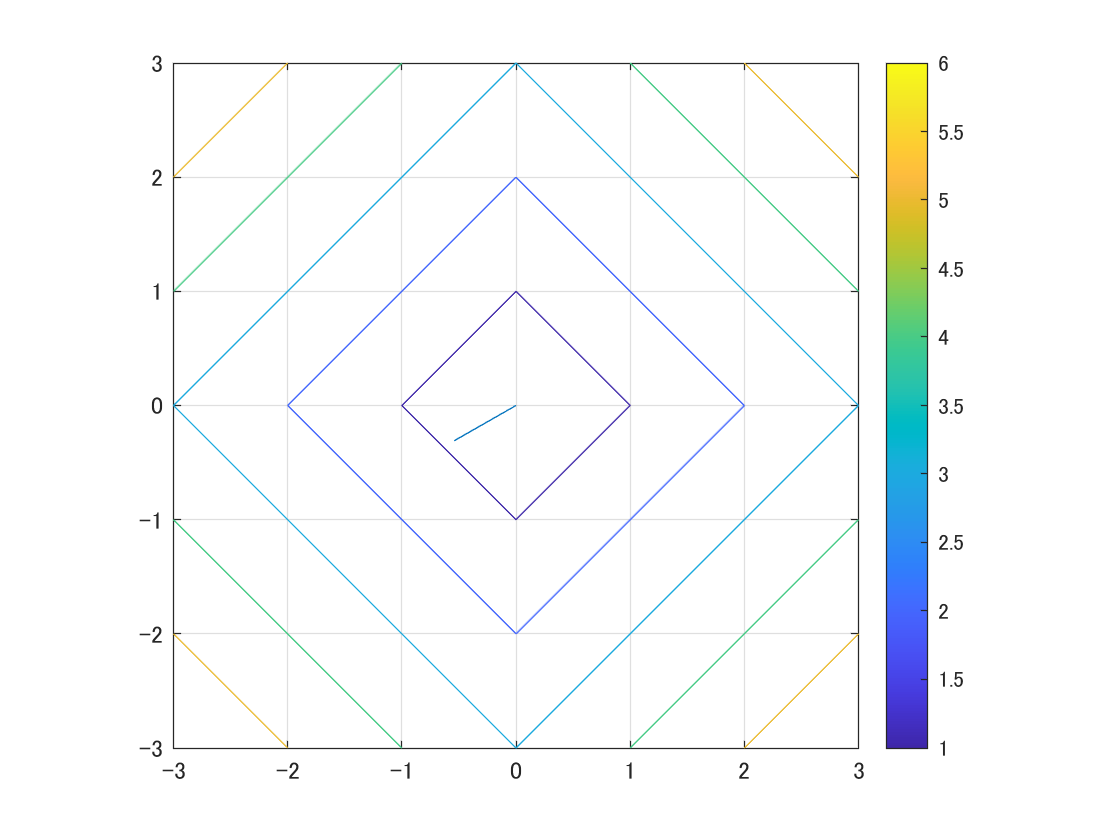


% Plot vector v with the contour plot of lp-norm if D=2
if ndim == 2
    % Plot of vector v
    plotv(v,'-')
    colormap('default')
    axis equal
    axis([-3 3 -3 3])
    grid on
    hold on
    % Contour plot of lp-norm
    fcontour(@(v1,v2) vecnorm([v1(:) v2(:)].',p),[-3 3 -3 3])
    colorbar
    hold off
end

### ベクトルとしてみた$N_1 \times N_2$配列の $\ell_p$-ノルム

($\ell_p$-norm of a $2\times 2$ array as a vector)


$$\|\mathbf{v}\|_{p}=\left(\sum_{j=0}^{N_2-1}\sum_{i=0}^{N_1-1}\left|v_{i,j}\right|^{p}\right)^{\frac{1}{p}}$$


ただし， $v_{i,j}$はベクトルとしてみた配列 $\mathbf{v}\in\mathbb{R}^{N_1\times N_2}$ の $i,j$-番目要素 $[\mathbf{v}]_{i,j}$。

( where $v_{i,j}$ stands for the $i,j$-th element of array $\mathbf{v}$ as a vector, i.e.,  $[\mathbf{v}]_{i,j}$.)

% Array dimension
ndim1 = 2

ndim1 = 2

ndim2 = 2

ndim2 = 2


% Generate a N1xN2 arrya v with normally distributed random numbers
v = randn(ndim1,ndim2)

v =    -1.0966   -0.1807
   -0.4930    0.0458


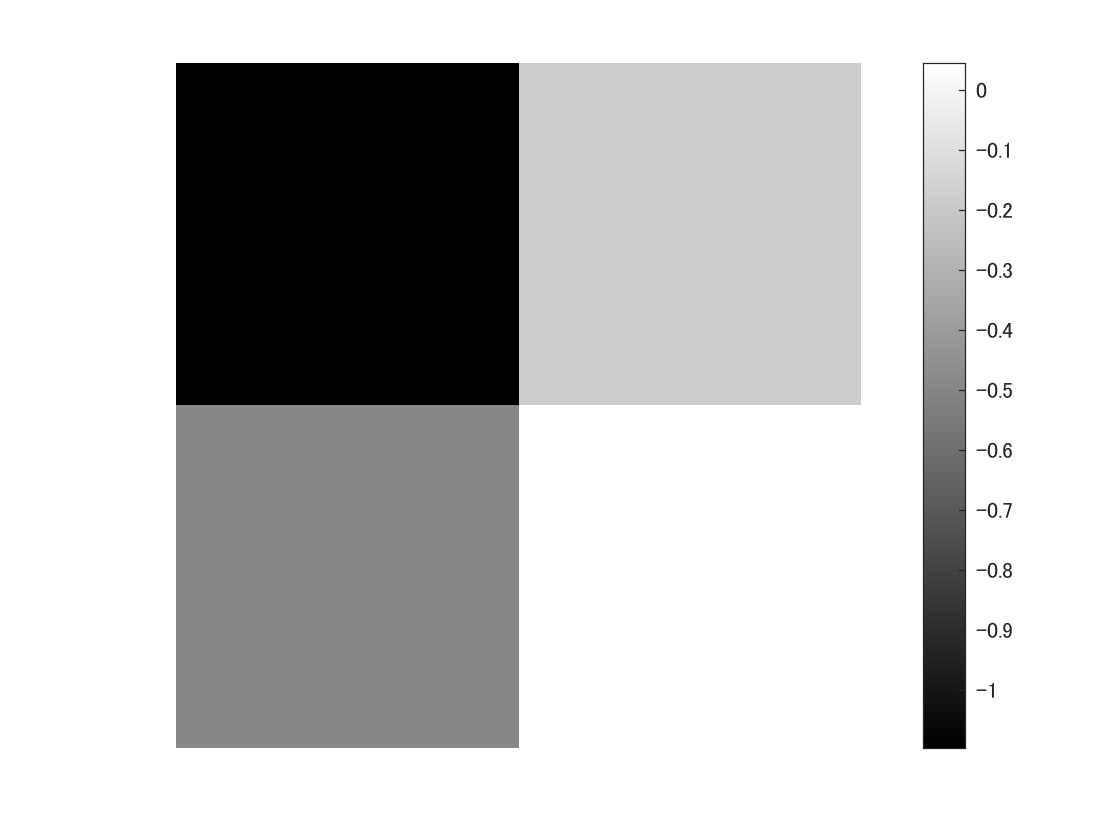


% Visualization of array v
imagesc(v)
colormap('gray')
colorbar
axis equal
axis off

% Setting of parameter p
p = 1

p = 1


% lp-(element-wise) norm of v
lpnorm = norm(v(:),p);
disp(['l' num2str(p) '-norm of array v: ' num2str(lpnorm)])

l1-norm of array v: 1.8162


© Copyright, Shogo MURAMATSU, All rights reserved.